# **Face Recognition**

#### **------------------------------------------------------------------------------------------------------------------------------------**

#### Pose Data

#### **------------------------------------------------------------------------------------------------------------------------------------**

data = load('pose.mat');
% 68 subjects; 13 different poses per subject.
pose = data.pose; % 48x40x13x68
%size(pose)

Illumination Data (additional data set for Pose)

data = load('illumination.mat');
% 68 subjects; 21 additional images for each subject.
illum = data.illum;  % 1920x21x68
%size(illum); 

#### ------------------------------------------------------------------------------------------------------------------------------------

#### Pre-Processing

#### ------------------------------------------------------------------------------------------------------------------------------------

1. There are a total of 68 subjects. Each subject has 13 pose matrices. Hence, we reshape each pose matrix for all 68 subjects from 48x40x13 to 13x1920;

    => then, we combine all 68 subjects' pose matrices to create array C [884x1920] for further processing.

[dr, dc, pnum, snum] = size(pose); % pnum is the size of class/category
fprintf('Total subjects/classes: %d, Number of poses per subject/class: %d\n',snum,pnum);

Total subjects/classes: 68, Number of poses per subject/class: 13


Q = zeros(pnum,dr*dc,snum); % to store each subject's reshaped pose matrices [13x1920x68]
C = zeros(pnum*snum,dr*dc); % to store the combined the pose vectors [884x1920]
for i = 1:snum
    for j = 1:pnum
        rv = pose(:,:,j,i);
        Q(j,:,i) = rv(:)';
    end
    C((pnum*(i-1))+1:(pnum*i),:) = Q(1:pnum,:,i);
end
% (example) reference:
%           Q(1,:,3) represents 1st pose vector of 3rd subject
%           C(27,:) represents 1st pose vector of 3rd subject
%           Q(:,:,3) represents all 13 poses (row vectors) of 3rd subject
%           C(27:39,:) represents all 13 poses poses (row vectors) of 3rd subject

2. Performing **Principal Component Analysis** to reduce the number of dimensions from 1920 to nPCA dimensions.

    => creating a projected array Y [884xnPCA] from C [884x1920]

% PCA
[U,Sig,V] = svd(C','econ'); % economy-size decomposition of C
nPCA = 20 % number of principal components

nPCA = 20

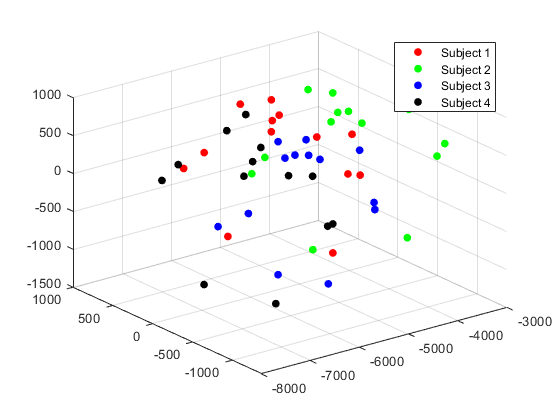

% project to nPCA-dimension space
Y = C*U(:,1:nPCA); % 884xnPCA (projected data)
%-----------------------------------------------------------------
% visualize Y for first four subjects in three dimensions (first three columns)
figure; hold on; grid;
% 1st subject
plot3(Y(1:13,1),Y(1:13,2),Y(1:13,3),'.','MarkerSize',20,'color','r'...
        ,'DisplayName','Subject 1');
% 2nd subject
plot3(Y(14:26,1),Y(14:26,2),Y(14:26,3),'.','MarkerSize',20,'color','g'...
        ,'DisplayName','Subject 2');
% 3rd subject
plot3(Y(27:39,1),Y(27:39,2),Y(27:39,3),'.','MarkerSize',20,'color','b'...
        ,'DisplayName','Subject 3');
% 4th subject
plot3(Y(40:52,1),Y(40:52,2),Y(40:52,3),'.','MarkerSize',20,'color','k'...
        ,'DisplayName','Subject 4');
view(3);
hold off;
legend('Location','northeast');

#### ------------------------------------------------------------------------------------------------------------------------------------

#### Test/Train Split

#### ------------------------------------------------------------------------------------------------------------------------------------

Total poses = 884 || Each subject has 13 poses (pnum). 

Training-set to have first **'k'** poses from each subject. Rest go into the testing-set.

training-set size [68*k by nPCA] ; testing-set size [68*(13-k) by nPCA] || where 13 is class size (pnum)  

k = 10;    % split size; 'k' has to be between 0 and 13
fprintf('Split %d/%d for each class\n',k,pnum-k);

Split 10/3 for each class


Y_train = zeros(snum*k,nPCA);
Y_test = zeros(snum*(pnum-k),nPCA);

t = 1;  %counter
v = 1;  %counter
for i = 1:pnum:snum*pnum
    % training set
    Y_train(t:t+k-1,:) = Y(i:i+k-1,:); % [68*k by nPCA]
    t = t + k;
    % testing set
    Y_test(v:v+(pnum-k)-1,:) = Y(i+k:i+pnum-1,:); % [68*(pnum-k) by nPCA]
    v = v + (pnum-k);
end

#### ------------------------------------------------------------------------------------------------------------------------------------

#### Classification

#### ------------------------------------------------------------------------------------------------------------------------------------

**I. k-NN Classifier **

nPCA dimensional space | Distance metric: Euclidean

Each row in the training set is an example/instance. Each row in the test set is an observation that needs to be

classified.

1. Finding Euclidean distance from each observation to each of the training data example/instance.

D = zeros(size(Y_train,1),size(Y_test,1));
for i = 1:size(Y_test,1)
    D(:,i) = sqrt(sum((Y_train-Y_test(i,:)).*(Y_train-Y_test(i,:)),2));
end
D;

2. Sorting the distances and retrieving nearest neighbors.

    Labelling each obs accordingly.

kNN = 25

kNN = 25

accuracy = zeros(kNN);
for n = 1:kNN
    label = zeros(size(Y_test,1),1);
    for i = 1:size(Y_test,1)
        sub = ceil(i/3);                % identifying correct label of the test subject
        [dsort,isort] = sort(D(:,i),'ascend');
        k_near_neigh = isort(1:n,:);
        correct_neigh = find((((sub-1)*k)<k_near_neigh) & (k_near_neigh<=(sub*k)));
        length(correct_neigh);
        if (length(correct_neigh) >= (n/2))
            label(i) = 1;
        else
            label(i) = -1;
        end
    end
    accuracy(n) = length(find(label==1))/size(Y_test,1);
    fprintf('Accuracy for k = %d nearest neigh.= %f\n',n,accuracy(n));
end

Accuracy for k = 1 nearest neigh.= 0.524510
Accuracy for k = 2 nearest neigh.= 0.612745
Accuracy for k = 3 nearest neigh.= 0.147059
Accuracy for k = 4 nearest neigh.= 0.166667
Accuracy for k = 5 nearest neigh.= 0.093137
Accuracy for k = 6 nearest neigh.= 0.098039
Accuracy for k = 7 nearest neigh.= 0.063725
Accuracy for k = 8 nearest neigh.= 0.078431
Accuracy for k = 9 nearest neigh.= 0.063725
Accuracy for k = 10 nearest neigh.= 0.068627
Accuracy for k = 11 nearest neigh.= 0.053922
Accuracy for k = 12 nearest neigh.= 0.058824
Accuracy for k = 13 nearest neigh.= 0.029412
Accuracy for k = 14 nearest neigh.= 0.039216
Accuracy for k = 15 nearest neigh.= 0.019608
Accuracy for k = 16 nearest neigh.= 0.019608
Accuracy for k = 17 nearest neigh.= 0.019608
Accuracy for k = 18 nearest neigh.= 0.019608
Accuracy for k = 19 nearest neigh.= 0.014706
Accuracy for k = 20 nearest neigh.= 0.014706
Accuracy for k = 21 nearest neigh.= 0.000000
Accuracy for k = 22 nearest neigh.= 0.000000
Accuracy for k = 23

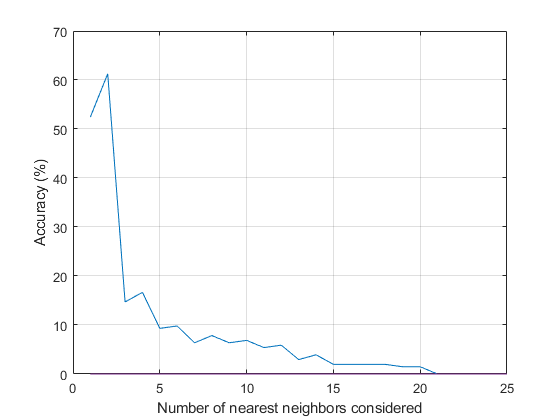


figure;
plot(1:kNN,accuracy*100,'LineWidth',0.5);
xlabel('Number of nearest neighbors considered');
ylabel('Accuracy (%)');
grid on;

**II. Bayes' Classifier **

**[ATTEMPT 1]**

1. Estimate the means for each class. || mu1, mu2, ... mu68

Split the projected training data (Y_train) into 68 matrices, one for each class.

Q_train = zeros(k,nPCA,snum);
l = 1;
for i = 1:k:size(Y_train,1)
    Q_train(:,:,l) = Y_train(i:i+k-1,:);
    l = l+1;
end
% mean for each class in the training set
mu = zeros(1,nPCA);
for i = 1:snum
    mu(i,:) = mean(Q_train(:,:,i),1);  % column-mean for each class
end
% NOTE: Q_test will be used later
Q_test = zeros(pnum-k,nPCA,snum);   
l = 1;
for i = 1:pnum-k:size(Y_test,1)
    Q_test(:,:,l) = Y_test(i:i+pnum-k-1,:);
    l = l+1;
end

2. Estimate the covariance matrices for each class. || S1,S2...S68

S = zeros(nPCA,nPCA,snum);
for i = 1:snum
    Qc = Q_train(:,:,i)-ones(k,1)*mu(i,:);  % center the data for each class
    S(:,:,i) = (Qc'*Qc)/k;       % Covariance matrices for each subject/class
end

3. Define discriminant function g(x) for N(mu1,S1),N(mu2,S2),...N(mu68,S68)

`Decision rule: For ith class, If gi(x)>gj(x) for i!=j, decide class 'i'`

Note: 'Equal Priors', i.e. P(w1) = P(w2) = .. = P(w68), since they all have equal number of poses

iS = zeros(nPCA,nPCA,snum);
for i = 1:snum
    iS = inv(S(:,:,i)); % calculating the inverse of the covariance matrices
end
warning('off')

**Note: We see that the covariance matrices appear to be singular since there are just 10 poses/data-points per subject. Hence, we will go forward with just using 5 subjects instead of 68. **

**-----------------------------------------------------------------------------------------------------------------------------------**

**II. Bayes' Classifier **

**[ATTEMPT 2]             "Using only 5 subjects: 1st,5th,10th,38th,63rd"**

1. Estimate the means for each class. || mu1, mu2, ... mu5

Split the projected training data (Y_train) into 5 matrices, one for each class.

Q_train = zeros(k,nPCA,5);          % using 5 subjects only (1st,5th,10th,38th,63rd)
l = 1;
for i = [1,5,10,38,63]
    idx(l) = k*(i-1)+1;
    l = l+1;
end
l = 1;
for i = 1:k:size(Y_train,1)
    if (i == idx(1))||(i == idx(2))||(i == idx(3))||(i == idx(4))||(i == idx(5))
        Q_train(:,:,l) = Y_train(i:i+k-1,:);
        l = l+1;
    end
end
% mean for each class in the training set
mu = zeros(1,nPCA);
for i = 1:5
    mu(i,:) = mean(Q_train(:,:,i),1);  % column-mean for each class
end

2. Estimate the covariance matrices for each class. || S1,S2...S5

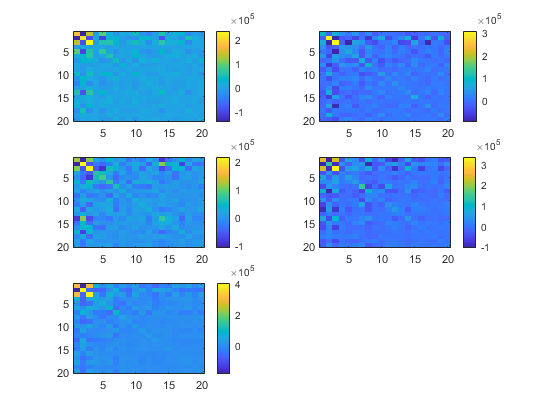

S = zeros(nPCA,nPCA,5);
for i = 1:5
    Qc = Q_train(:,:,i)-ones(k,1)*mu(i,:);  % center the data for each class
    S(:,:,i) = (Qc'*Qc)/k;       % Covariance matrices for each subject/class
end
%--------------------------------------------------------------------
% visualizing the covariance matrices to compare 1st, 5th, 10th, 38th, and 63rd subject
% we see that the matrices look pretty different 
figure; grid;
subplot(3,2,1);
imagesc(S(:,:,1));
colorbar;
subplot(3,2,2);
imagesc(S(:,:,2));
colorbar;
subplot(3,2,3);
imagesc(S(:,:,3));
colorbar;
subplot(3,2,4);
imagesc(S(:,:,4));
colorbar;
subplot(3,2,5);
imagesc(S(:,:,5));
colorbar;

3. Classifying the test set

`Decision rule: For ith class, If gi(x)>gj(x) for i!=j, decide class 'i'`

Note: 'Equal Priors', i.e. P(w1) = P(w2) = .. = P(w5), since they all have equal number of poses

% Retrieving the test set for five subjects
l = 1;
for i = [1,5,10,38,63]
    idx(l) = (pnum-k)*(i-1)+1;
    l = l+1;
end
Q_test = zeros(pnum-k,nPCA,5);   
l = 1;
for i = 1:pnum-k:size(Y_test,1)
    if (i == idx(1))||(i == idx(2))||(i == idx(3))||(i == idx(4))||(i == idx(5))
        Q_test(:,:,l) = Y_test(i:i+pnum-k-1,:);
        l = l+1;
    end
end

iS = zeros(nPCA,nPCA,5);
for i = 1:5
    iS(:,:,i) = inv(S(:,:,i)); % calculating the inverse of the covariance matrices
end
warning('off')
mu = mu';
w0 = zeros(5,5);
% testing
labels = zeros(5,5,pnum-k,5);
for p = 1:5
    for q = 1:pnum-k
        fprintf('test case# %d (actual class= %d)',q,p);
        y = Q_test(q,:,p)';  % TEST CASE
        for i = 1:5
            for j = 1:5
                if (i~=j)
                    % DISCRIMINANT FUNCTION
                    w0(i,j) = 0.5*(log(det(S(:,:,j))/det(S(:,:,i)))) - ...
                        0.5*(mu(:,i)'*iS(:,:,i)*mu(:,i) - mu(:,j)'*iS(:,:,j)*mu(:,j));
                    G = -0.5*y'*(iS(:,:,i)-iS(:,:,j))*y +...
                        y'*(iS(:,:,i)*mu(:,i) - iS(:,:,j)*mu(:,j)) + w0(i,j);
                    fprintf('i: %d, j: %d, sign(G)=%d\n',i,j,sign(G));
                else
                    G=0;
                end
                if (sign(G)>0)
                    labels(j,i,q,p) = i;
                elseif (sign(G)<0)
                    labels(j,i,q,p) = j;
                end
            end
        end
    end
end

test case# 1 (actual class= 1)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 2 (actual class= 1)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 3 (actual class= 1)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 1 (actual class= 2)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=-1
i: 4, j: 5, sign(G)=-1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=1


test case# 2 (actual class= 2)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 3 (actual class= 2)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=-1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 1 (actual class= 3)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 2 (actual class= 3)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 3 (actual class= 3)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=-1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=1
i: 5, j: 4, sign(G)=-1


test case# 1 (actual class= 4)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=-1
i: 4, j: 5, sign(G)=-1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=1


test case# 2 (actual class= 4)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 3 (actual class= 4)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=-1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=-1
i: 4, j: 5, sign(G)=-1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=1


test case# 1 (actual class= 5)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 2 (actual class= 5)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=-1
i: 2, j: 4, sign(G)=-1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


test case# 3 (actual class= 5)

i: 1, j: 2, sign(G)=1
i: 1, j: 3, sign(G)=1
i: 1, j: 4, sign(G)=1
i: 1, j: 5, sign(G)=1
i: 2, j: 1, sign(G)=-1
i: 2, j: 3, sign(G)=1
i: 2, j: 4, sign(G)=1
i: 2, j: 5, sign(G)=1
i: 3, j: 1, sign(G)=-1
i: 3, j: 2, sign(G)=-1
i: 3, j: 4, sign(G)=-1
i: 3, j: 5, sign(G)=1
i: 4, j: 1, sign(G)=-1
i: 4, j: 2, sign(G)=-1
i: 4, j: 3, sign(G)=1
i: 4, j: 5, sign(G)=1
i: 5, j: 1, sign(G)=-1
i: 5, j: 2, sign(G)=-1
i: 5, j: 3, sign(G)=-1
i: 5, j: 4, sign(G)=-1


*display*

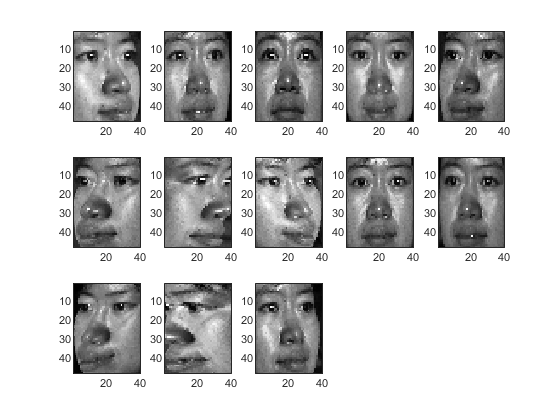

% displaying all 13 poses for 1st subject
figure;
colormap gray
for j = 1:15
    if(j<=pnum)
        subplot(3,5,j);
        imagesc(pose(:,:,j,1));
    end
end

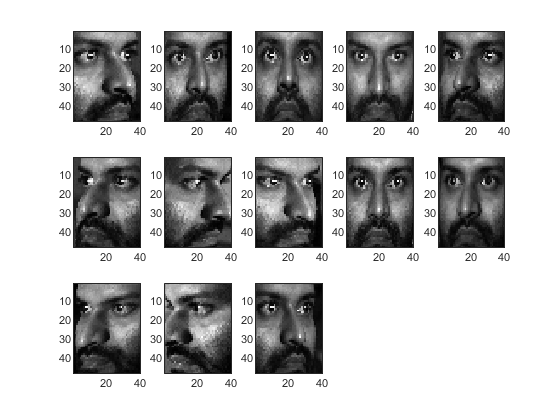


% displaying all 13 poses for 5th subject
figure;
colormap gray
for j = 1:15
    if(j<=pnum)
        subplot(3,5,j);
        imagesc(pose(:,:,j,10));
    end
end

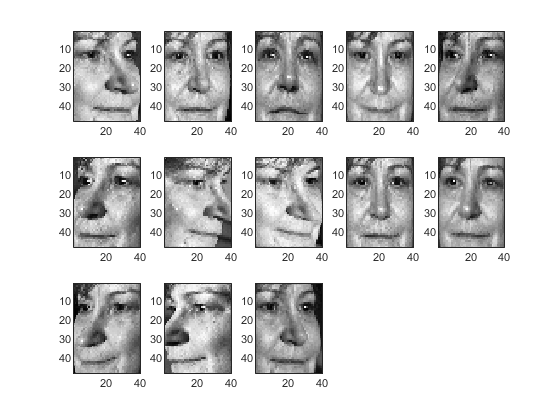


% displaying all 13 poses for 10th subject
figure;
colormap gray
for j = 1:15
    if(j<=pnum)
        subplot(3,5,j);
        imagesc(pose(:,:,j,38));
    end
end

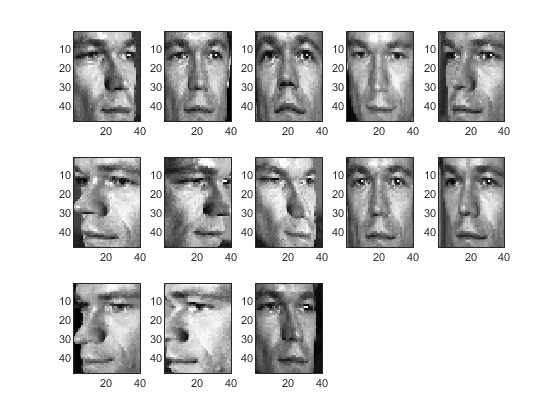


% displaying all 13 poses for 38th subject
figure;
colormap gray
for j = 1:15
    if(j<=pnum)
        subplot(3,5,j);
        imagesc(pose(:,:,j,5));
    end
end

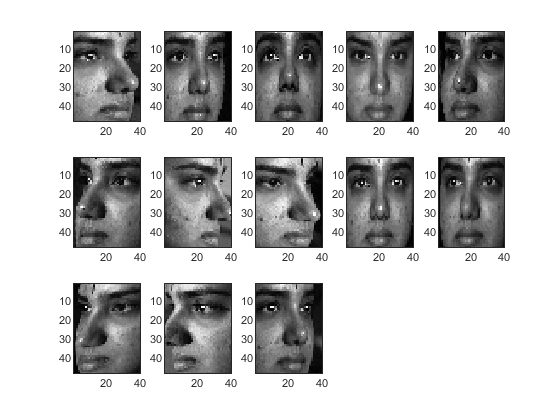


% displaying all 13 poses for 63rd subject
figure;
colormap gray
for j = 1:15
    if(j<=pnum)
        subplot(3,5,j);
        imagesc(pose(:,:,j,63));
    end
end

**------------------------------------------------------------------------------------------------------------------------------------**